# Mars Rover: Final Project

Follow the instructions provided in the course to complete your final project. 

### Load the images

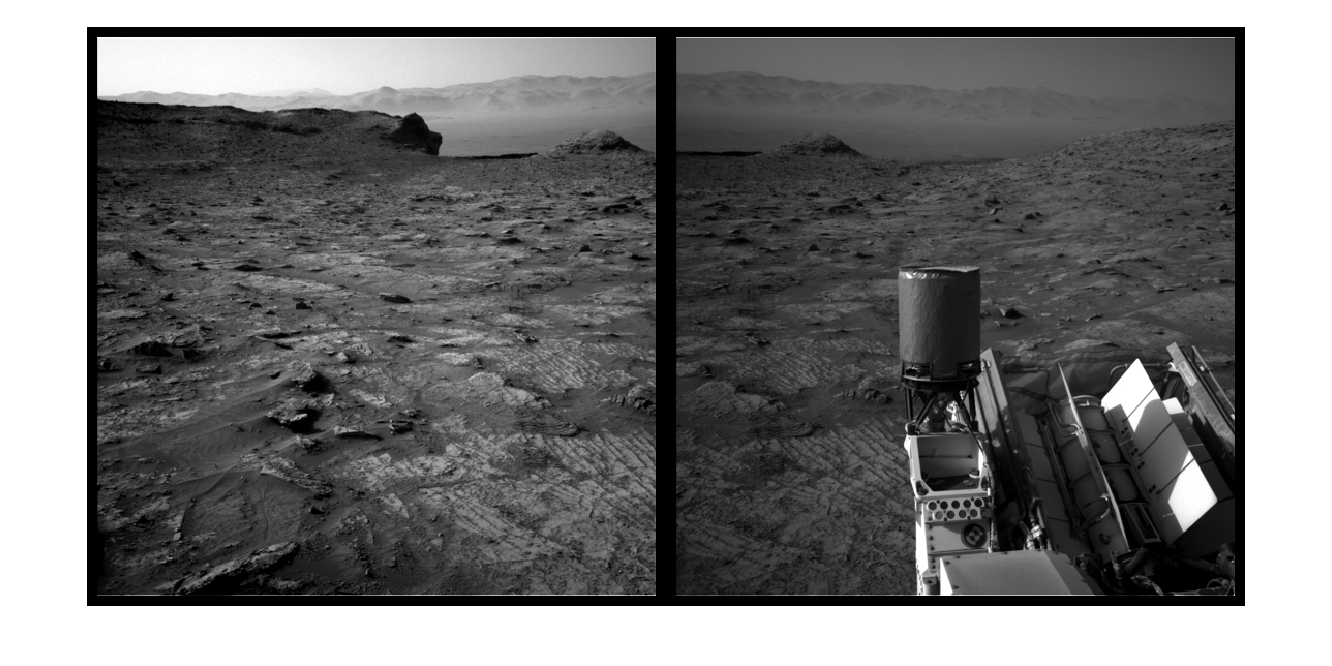

fixedImg = imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG");
movingImg = imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG");

montage({movingImg, fixedImg},"BorderSize",[10 10])

### Register the Images

Use the Registration Estimator app to create a function that registers the images. Then, use that function to return the registration structure.

When you're happy with your registration function, return to the course and use the online grader to check if it gives the correct result.

reg = registerMarsRoverImages(movingImg, fixedImg)

reg = struct with fields:
     FixedMatchedFeatures: [10×1 SURFPoints]
    MovingMatchedFeatures: [10×1 SURFPoints]
           Transformation: [1×1 projective2d]
          RegisteredImage: [1024×1024 uint8]
            SpatialRefObj: [1×1 imref2d]


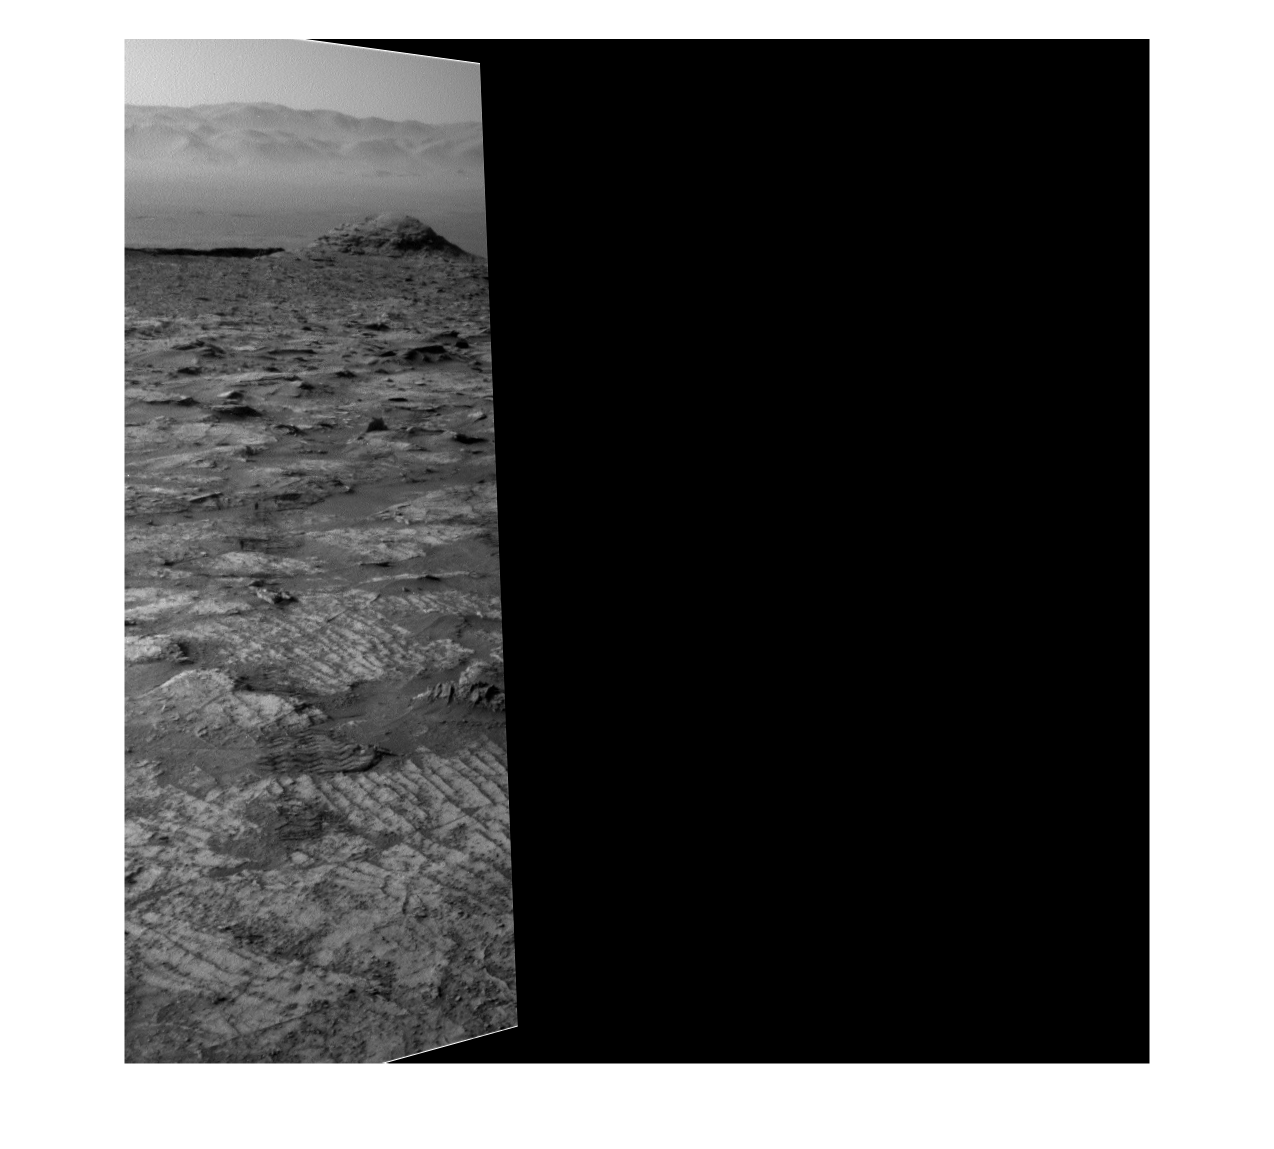


figure; imshow(reg.RegisteredImage)

### Initialize the Panorama

Use your geometric transformation to determine the world coordinates and initialize an empty panorama image. Here, recall that you're working with **grayscale** images, unlike the color concrete images.

When you're done, return to the course and take the quiz to check if your panorama dimensions are as expected.

movingT = reg.Transformation;
fixedT = rigidtform2d();
[nrows, ncols, ~] = size(movingImg);
[xlimMoving, ylimMoving] = outputLimits(movingT, [1 ncols], [1 nrows]);
[xlimFixed, ylimFixed] = outputLimits(fixedT, [1 ncols], [1 nrows]);

xMin = min([xlimMoving, xlimFixed]);
xMax = max([xlimMoving, xlimFixed]);
yMin = min([ylimMoving, ylimFixed]);
yMax = max([ylimMoving, ylimFixed]);

w = round(xMax - xMin);
h = round(yMax - yMin);

panorama = zeros([h, w], "uint8")

panorama = 1555×2087 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

### Create the Panorama

Use the `vision.AlphaBlender `object to create the final panorama. When you're done, pass your final image to the `testMarsImage` function to see if it's correct. 

If you're correct, go back to the quiz and add the numeric code to complete the course!

If you get a dimension error while using `AlphaBlender`, double check that you are initializing the empty panorama correctly for a grayscale image. Remember that the third dimension of a color image has size 3, but the third dimension of a grayscale image only has size 1.

blender = vision.AlphaBlender("Operation","Binary Mask", "MaskSource", "Input port")

blender =   vision.AlphaBlender with properties:

         Operation: 'Binary mask'
        MaskSource: 'Input port'
    LocationSource: 'Property'
          Location: [1 1]


panoramaView = imref2d([h w], [xMin xMax], [yMin yMax]);
movingWarped = imwarp(movingImg, movingT, "OutputView", panoramaView);
fixedWarped = imwarp(fixedImg, fixedT, "OutputView", panoramaView);
mask = ones(nrows, ncols, "logical");
fixedMask = imwarp(mask, fixedT, "OutputView", panoramaView);
movingMask = imwarp(mask, movingT, "OutputView", panoramaView);

panorama = blender(panorama,movingWarped,movingMask);
% Add the second image
panorama = blender(panorama,fixedWarped,fixedMask);
testMarsImage(panorama)

Success!
Enter the number: 1984 into the final quiz question.


*Copyright 2022 The MathWorks, Inc.*